n = 6;                   % Number of toltal Nodes
L_tot = 5; % [m]         % Total length of shaft
L = L_tot/n;             % Length Of each node
r_s = 0.1;               % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;

pi = 3.1415

pi = 3.1415

S = pi*r_s^2             % Shaft Cross section Area

S = 0.0314

I = pi*r_s^4/4

I = 7.8538e-05


M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref =    75.8448         0         0   -8.9134   26.2540         0         0    5.2670
         0   75.8448    8.9134         0         0   26.2540   -5.2670         0
         0    8.9134    1.3505         0         0    5.2670   -1.0129         0
   -8.9134         0         0    1.3505   -5.2670         0         0   -1.0129
   26.2540         0         0   -5.2670   75.8448         0         0    8.9134
         0   26.2540    5.2670         0         0   75.8448   -8.9134         0
         0   -5.2670   -1.0129         0         0   -8.9134    1.3505         0
    5.2670         0         0   -1.0129    8.9134         0         0    1.3505



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*rho_s*I/(30*L)

M_s =     0.8821         0         0   -0.0613   -0.8821         0         0   -0.0613
         0    0.8821    0.0613         0         0   -0.8821    0.0613         0
         0    0.0613    0.0681         0         0   -0.0613   -0.0170         0
   -0.0613         0         0    0.0681    0.0613         0         0   -0.0170
   -0.8821         0         0    0.0613    0.8821         0         0    0.0613
         0   -0.8821   -0.0613         0         0    0.8821   -0.0613         0
         0    0.0613   -0.0170         0         0   -0.0613    0.0681         0
   -0.0613         0         0   -0.0170    0.0613         0         0    0.0681


     
M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + M_s(1+i,1+j);
            end
        end
    end
end


D_d = 1;                                   % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.5;                                 % Disk Width
rho_d = 7850;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d;  % Disk Inertia

n_d = 3;                                   % Number Of Node(s) Which Disk is Located
M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix

k = n_d - 1

k = 2

if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
        end
    end
end
 
      
C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0   -1.7643   -0.1225         0         0    1.7643   -0.1225         0
    1.7643         0         0   -0.1225   -1.7643         0         0   -0.1225
    0.1225         0         0   -0.1361   -0.1225         0         0    0.0340
         0    0.1225    0.1361         0         0   -0.1225   -0.0340         0
         0    1.7643    0.1225         0         0   -1.7643    0.1225         0
   -1.7643         0         0    0.1225    1.7643         0         0    0.1225
    0.1225         0         0    0.0340   -0.1225         0         0   -0.1361
         0    0.1225   -0.0340         0         0   -0.1225    0.1361         0


  
C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
            end
        end
    end
end      
      
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
       0    12   6*L       0         0     -12    6*L       0;
       0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
      -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
      -12   0    0         6*L       12     0     0         6*L;
       0   -12  -6*L       0         0      12   -6*L       0;
       0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
      -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 	1.0e+08 *

    3.2571         0         0   -1.3571   -3.2571         0         0   -1.3571
         0    3.2571    1.3571         0         0   -3.2571    1.3571         0
         0    1.3571    0.7540         0         0   -1.3571    0.3770         0
   -1.3571         0         0    0.7540    1.3571         0         0    0.3770
   -3.2571         0         0    1.3571    3.2571         0         0    1.3571
         0   -3.2571   -1.3571         0         0    3.2571   -1.3571         0
         0    1.3571    0.3770         0         0   -1.3571    0.7540         0
   -1.3571         0         0    0.3770    1.3571         0         0    0.7540


  
F = 1;      
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =     1.4400         0         0   -0.1000   -1.4400         0         0   -0.1000
         0    1.4400    0.1000         0         0   -1.4400    0.1000         0
         0    0.1000    0.1111         0         0   -0.1000   -0.0278         0
   -0.1000         0         0    0.1111    0.1000         0         0   -0.0278
   -1.4400         0         0    0.1000    1.4400         0         0    0.1000
         0   -1.4400   -0.1000         0         0    1.4400   -0.1000         0
         0    0.1000   -0.0278         0         0   -0.1000    0.1111         0
   -0.1000         0         0   -0.0278    0.1000         0         0    0.1111



K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              K(1+k*4+i,1+k*4+j)=K(1+k*4+i,1+k*4+j)+K_C(1+i,1+j)+K_F(1+i,1+j);
            end
        end
    end
end


landa=inv(M)*K;
[Eivec,Eival] = eig(landa)

Eivec =    0.0002 + 0.0000i   0.0003 + 0.0000i  -0.0794 + 0.0000i  -0.0136 + 0.0000i   0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.1314 + 0.0000i   0.0012 + 0.0000i   0.0012 + 0.0000i   0.0013 + 0.0000i  -0.3118 + 0.0000i   0.0005 + 0.0000i   0.0007 + 0.0000i   0.3070 + 0.0000i   0.0362 + 0.0000i   0.0044 + 0.0000i   0.4967 + 0.0000i  -0.2255 + 0.0000i  -0.4550 + 0.0000i   0.0349 + 0.0000i   0.3781 + 0.0000i   0.3781 - 0.0000i   0.0583 + 0.1930i   0.0583 - 0.1930i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0783 + 0.0000i   0.0002 + 0.0000i   0.0003 + 0.0000i   0.0000 + 0.0000i  -0.1313 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0010 + 0.0000i   0.0011 + 0.0000i   0.0544 + 0.0000i  -0.0084 + 0.0000i   0.0369 + 0.0000i   0.0401 + 0.0000i   0.4444 + 0.0000i   0.1183 + 0.0000i  -0.4688 + 0.0000i   0.0260 + 0.1537i   0.0260 - 0.1537i  -0.3550 - 0.0000i  -0.3550 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.9425 + 0.0000i  

Eival = 	1.0e+08 *

   3.5413 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0380 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0790 + 0.0000i   0.0000

[Eival_sorted, ind] = sort(diag(Eival),'ascend');
Eivec_sorted = Eivec(:,ind);

nat_freq_1 = sqrt(Eival_sorted(1))

nat_freq_1 = 3.4928e-05 - 5.2055e-05i

nat_freq_2 = sqrt(Eival_sorted(2))

nat_freq_2 = 3.4928e-05 + 5.2055e-05i

nat_freq_3 = sqrt(Eival_sorted(3))

nat_freq_3 = 0.0464 - 0.0000i

nat_freq_4 = sqrt(Eival_sorted(4))

nat_freq_4 = 0.0464 + 0.0000i

nat_freq_5 = sqrt(Eival_sorted(5))

nat_freq_5 = 224.8204

nat_freq_6 = sqrt(Eival_sorted(6))

nat_freq_6 = 224.8204

nat_freq_7 = sqrt(Eival_sorted(7))

nat_freq_7 = 497.3946

nat_freq_8 = sqrt(Eival_sorted(8))

nat_freq_8 = 497.3946

nat_freq_9 = sqrt(Eival_sorted(9))

nat_freq_9 = 955.1438

nat_freq_10 = sqrt(Eival_sorted(10))

nat_freq_10 = 955.1438


mode_shape = zeros(n*4);

for j = 1:n*4
    for i = 1:n*4
        mode_shape(i,j) = Eivec_sorted(i,j);
    end
end


% C = C*omega
% r = .5*inv(M)*(-C + sqrt((C)^2 - 4*M*K))

u = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        u(i+1,j) = real(mode_shape(i*4 + 1,j));
    end
end

% ==========================================================
% M_diag = zeros(n*4);
% for i = 1:n*4
%     M_diag(i,i)=transpose(mode_shape(:,i))*M*mode_shape(:,i);
% end
% 
% 
% 
% K_diag = zeros(n*4);
% for i = 1:n*4
%     K_diag(i,i)=transpose(mode_shape(:,i))*K*mode_shape(:,i);
% end
% 
% C_diag = zeros(n*4);
% for i = 1:n*4
%     C_diag(i,i)=transpose(mode_shape(:,i))*C*mode_shape(:,i);
% end
% ======================================================

M_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        M_diag_test(i,j)=transpose(mode_shape(:,i))*M*mode_shape(:,j);
    end
end

K_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        K_diag_test(i,j)=transpose(mode_shape(:,i))*K*mode_shape(:,j);
    end
end

C_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        C_diag_test(i,j)=transpose(mode_shape(:,i))*C*mode_shape(:,j);
    end
end

% C_diag = C_diag*omega
% r = .5*inv(M_diag)*(-C_diag + sqrt((C_diag)^2 - 4*M_diag*K_diag))
syms omega
assume(omega,'real')
C_diag_test = C_diag_test*omega

C = C*omega


% r = .5*inv(M_diag_test)*(-C_diag_test + sqrt((C_diag_test)^2 - 4*M_diag_test*K_diag_test))
% A = [ 0          eye(n*4); 
%      -inv(K)*M  -inv(K)*C]
% B = [r*P; P]
% A*B = r^(-1)*B


% r = sym('r', [1,2*n*4])
% r = diag(r)
% delta = sym('delta', [n*4,n*4])

syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C]

B = [M  zeros(n*4);zeros(n*4)  -K]

B = 	1.0e+08 *

    0.0000         0         0   -0.0000    0.0000         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000  

% X = [r*delta; delta]

eqn = det(A - (lan).*B)

vpa(eqn,2)

S = solve(vpa(eqn,2),lan)

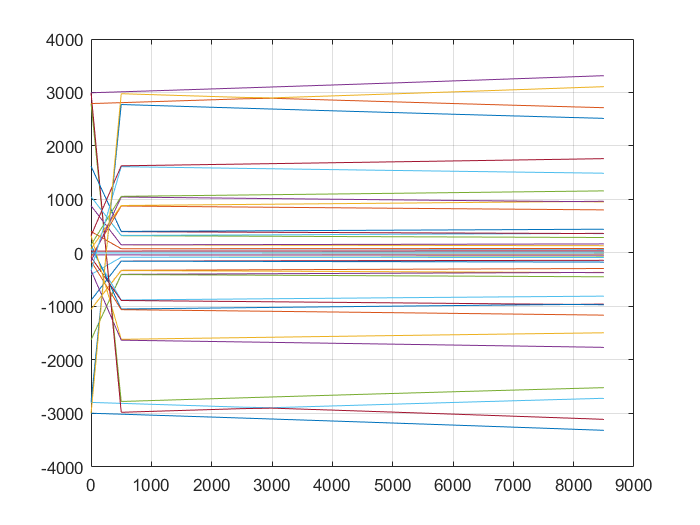

clear w
for omega= 1:500:9000
    S_new = subs(S,'omega',omega);
    landa = vpa(S_new);
    w(:,round(omega/500) + 1) = imag(1./landa);
    F = w./(2*pi);
end

omega= 1:500:9000;
plot(omega,F)
grid on